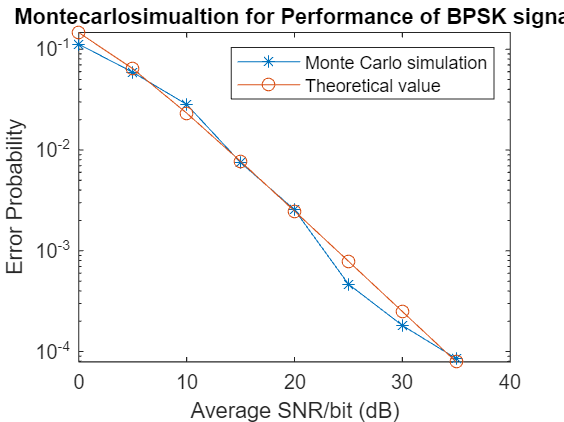

clc;
clear;
Eb=1;
EbNo_dB=0:5:35;
N2=Eb*10.^(-EbNo_dB/10);   %No/2  noise power
s=1; %standard deviation
v=s^2; %variance
len=length(EbNo_dB);

BER=zeros(1,len);

for i=1:len
    err=0;bits=0;
    while err<=10
        u=rand;
        r=sqrt(-2*v*log(u));
        noise=sqrt(N2(i))*randn;
        y=r*sqrt(Eb)+noise;
        if y<=0
            yd=1;
        else
            yd=0;
        end  %if end
        bits=bits+1;
        err=err+yd;
    end   %while end
    BER(i)=err/bits;
end   %for end

p=v*Eb./N2;
pe=0.5*(1-sqrt(p./(1+p)));  %BPSK Pe

semilogy(EbNo_dB,BER,'-*',EbNo_dB,pe,'-o');
title('Montecarlosimualtion for Performance of BPSK signal');
xlabel('Average SNR/bit (dB)')
ylabel('Error Probability')
legend('Monte Carlo simulation','Theoretical value')